# ORR - lab 3 - Nonlinear Model Predictive Control (NMPC)

You learned the basics of how Model Predictive Control (MPC) works and how it is applied to control of linear models in one of the previous lectures. Since real systems often are nonlinear and a linear approximation of them may not suffice, it's time to step up and apply the principles of MPC to nonlinear models. Seemingly, this should be simple as the principle of optimizing the control sequence over a prediction horizon at every control period can be applied to nonlinear models as well as to linear models. For nonlinear models, the receding horizon optimization problem to be solved at every control period may be formulated as follows:


$$
\begin{array}{rl}
       \min_{\mathbf{x}_{0}, \dots, \mathbf{x}_N, \mathbf{u}_0, \dots, \mathbf{u}_{N-1}}& V_N(\mathbf{x}_N) + \sum_{k=0}^{N-1} V(\mathbf{x}_k, \mathbf{u}_k) \\
       \mathrm{s.t.}:  &\mathbf{x}_{0} = \hat{\mathbf{x}}_i,\\
&\mathbf{x}_{k+1} = f(\mathbf{x}_k, \mathbf{u}_k), \qquad k=0,\dots,N-1\\
& h(\mathbf{x}_k, \mathbf{u}_k) \leq 0, \qquad \quad\  k=0,\dots,N-1\\
& h_N(\mathbf{x}_N) \leq 0.
\end{array}
$$


As opposed to linear MPC, the cost functions $V_N$ and $V$ are more general functions (recall that the cost functions are quadratic in linear MPC). Similarly, the dynamics $F$ and path constraints $h$ and $h_N$ can be nonlinear (whereas these functions are linear in linear MPC). As minor as it seems, this difference has a huge impact on how one solves the receding horizon optimization problem. Now, we need to solve a general *Nonlinear Programming (NLP)* problem and that—as opposed to *Quadratic Programming (QP)* problem in linear MPC—tends to be slow. Why? One approach to solving NLPs is a so-called *Sequential Quadratic Programming (SQP)* method [2]. This method proceeds iteratively. At each iteration, the method approximates the NLP at hand by a QP for the current values of the optimization variables, solves the QP, and updates the optimization variables accordingly. Then it proceeds to the next iteration. You can immediately see that it takes more time to solve an NLP than QP because you have to actually solve many QPs to solve an NLP.

You can invoke a general NLP solver like fmincon() in Matlab, IPOPT, SNOPT, or some other for solving the aftermentioned nonlinear receding horizon optimization. That would work fine but, as has already been explained, could be very slow. By the way, this is what *Model Predictive Control toolbox* in Matlab does when you use it for designing NMPC. It formulates the associated NLP and solves it by fmincon(). Since the time needed for solving the receding horizon optimization problem is of crucial importance, we often need a more efficient method for solving it. Here, we use a so-called *Real-time Iteration (RTI)* approach [1]. Briefly, RTI uses SQP for solving the receding horizon optimization problem, but it cleverly initializes the SQP method and does only one iteration of it.

## Sequential Quadratic Programming with Gauss-Newton Hessian approximation

As mentiond, SQP method approximates the NLP by a QP. This may remind you the *Newton method* from unconstrained optimization. And rightly so. You may also remember that calculating the Hessian could be expensive and also that one has to handle properly the case when the Hessian becomes indefinite. To avoid these issues, we can use a quasi-Newton method where the Hessian is easier to compute and guaranteed to be positive definite. SQP methods suffers from the same issues but we can also use the same solution: we approximate the Hessian so that it is guaranteed to be positive definite. We will use *Gauss-Newton Hessian* approximation and for that, we need the cost functions to have a specific form: $V_N(\mathbf{x}_N)=\|r(\mathbf{x}_N)\|_2^2$ and $V(\mathbf{x}_k, \mathbf{u}_k)=\frac{1}{2}\|r(\mathbf{x}_k, \mathbf{u}_k)\|_2^2$. 

SQP method with Gauss-Newton Hessian approximation converts the nonlinear receding horizon optimazation problem to


$$
\begin{array}{rl}
       \min_{\Delta\mathbf{x}_{0}, \dots, \Delta\mathbf{x}_N, \Delta\mathbf{u}_0, \dots, \Delta\mathbf{u}_{N-1}}& \frac{1}{2}\Delta\mathbf{x}_N^T\mathbf{W}_N \Delta\mathbf{x}_N + \mathbf{J}_N^T\Delta\mathbf{x}_N + \sum_{k=0}^{N-1} \frac{1}{2}\left[\matrix{ \Delta\mathbf{x}_k^T & \Delta\mathbf{u}_k^T} \right] \mathbf{W}_k\left[\matrix{ \Delta\mathbf{x}_k \cr \Delta\mathbf{u}_k} \right] + \mathbf{J}_k^T\left[\matrix{ \Delta\mathbf{x}_k \cr \Delta\mathbf{u}_k} \right] \\
       \mathrm{s.t.}:  &\Delta\mathbf{x}_{0} = \hat{\mathbf{x}}_i - \mathbf{x}_0^\mathrm{g},\\
&\Delta\mathbf{x}_{k+1} = \mathbf{A}_k\Delta\mathbf{x}_k +  \mathbf{B}_k\Delta\mathbf{u}_k + \mathbf{r}_k, \qquad k=0,\dots,N-1\\
&\mathbf{C}_k\Delta\mathbf{x}_k +  \mathbf{D}_k\Delta\mathbf{u}_k + h(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g}) \leq 0, \quad k=0,\dots,N-1\\
& \mathbf{H}_N\Delta\mathbf{x}_N + h_N(\mathbf{x}_N^\mathrm{g}) \leq 0.
\end{array}
$$


where $\mathbf{x}_{k=0,\dots,N}^\mathrm{g}$ and $\mathbf{u}_{k=0,\dots,N-1}^\mathrm{g}$ are current guesses of the optimal state and control trajectory, $\hat{\mathbf{x}}_i$ is an estimate of the state at the current control period,$\Delta\mathbf{x}_k = \mathbf{x}_k - \mathbf{x}_k^\mathrm{g} $ and $\Delta\mathbf{u}_k = \mathbf{u}_k - \mathbf{u}_k^\mathrm{g} $ are the new decision variables and the matrices are:


$$\mathbf{W}_k = \mathbf{R}_k^T\mathbf{R}_k, \\

\mathbf{R}_{k=0,\dots,N-1} =  \left[ \matrix{ \frac{\partial r(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g})}{\partial{\mathbf{x}_k}} & \frac{\partial r(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g})}{\partial{\mathbf{u}_k}} }\right], \quad
\mathbf{R}_N =  \frac{\partial r(\mathbf{x}_N^\mathrm{g})}{\partial{\mathbf{x}_N}}, \\

\mathbf{J}_{k=0,\dots,N-1} = \left[ \matrix{\nabla_{\mathbf{x}_k} V(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g}) \cr \nabla_{\mathbf{u}_k} V(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g}) } \right] ,\quad
\mathbf{J}_N = \nabla_{\mathbf{x}_N} V_N(\mathbf{x}_N^\mathrm{g}), \\

\mathbf{A}_k = \frac{\partial f(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g})}{\partial\mathbf{x}_k}, \quad
\mathbf{B}_k = \frac{\partial f(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g})}{\partial\mathbf{u}_k}, \quad
\mathbf{r}_k = f(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g}) - \mathbf{x}_{k+1}^\mathrm{g},\\

\mathbf{C}_k = \frac{\partial h(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g})}{\partial\mathbf{x}_k}, \quad
\mathbf{D}_k = \frac{\partial h(\mathbf{x}_k^\mathrm{g}, \mathbf{u}_k^\mathrm{g})}{\partial\mathbf{u}_k}, \quad
\mathbf{H}_N = \frac{\partial h(\mathbf{x}_N^\mathrm{g})}{\partial\mathbf{x}_N}. \\$$


Having the QP formulation, one can proceed to expressing the QP in a matrix form so that one can use any available QP solver to solve it. We stack the optimization variables $\Delta\mathbf{x}_k$ and $\Delta\mathbf{u}_k$ to a vector $\mathbf{z}$ as follows: $\mathbf{z} = [\Delta\mathbf{x}_0^T, \Delta\mathbf{u}_0^T, \dots, \Delta\mathbf{x}_{N-1}^T, \Delta\mathbf{u}_{N-1}^T, \Delta\mathbf{x}_N^T]^T$. Then, the QP in a matrix form is:


$$
\begin{array}{rl}
       \min_{\mathbf{z}}& \frac{1}{2}\mathbf{z}^T\bar{\mathbf{H}}\mathbf{z} + \bar{\mathbf{g}^T\mathbf{z}}\\
       \mathrm{s.t.}:  &\bar{\mathbf{A}}\mathbf{z} = \bar{\mathbf{b}}(\hat{\mathbf{x}}_i),\\
&\bar{\mathbf{M}}\mathbf{z} \leq \bar{\mathbf{m}},
\end{array}
$$


where


$$\bar{\mathbf{H}} = 
\left[
\matrix{
\mathbf{W}_0 & & & \cr
 & \mathbf{W}_1 & & \cr
& &\ddots &  \cr
& & & \mathbf{W}_N}
\right],
\qquad
\bar{\mathbf{g}} = 
\left[
\matrix{
\mathbf{J}_0\cr
\mathbf{J}_1\cr
\vdots\cr
\mathbf{J}_N\cr
}
\right],$$



$$\bar{\mathbf{A}} = 
\left[
\matrix{
\mathbf{I}_n & & & & & & & & \cr
-\mathbf{A}_0 & -\mathbf{B}_0 &\mathbf{I}_n & & & & & & \cr
& &-\mathbf{A}_1 & -\mathbf{B}_1 &\mathbf{I}_n & & & & \cr
& & &  & & \ddots & & & \cr
& & &  & & &-\mathbf{A}_{N-1} & -\mathbf{B}_{N-1}  & \mathbf{I}_n \cr
}
\right],
\qquad
\bar{\mathbf{b}}(\hat{\mathbf{x}}_i) = 
\left[
\matrix{
\hat{\mathbf{x}}_i - \mathbf{x}_0^\mathrm{g}\cr
f(\mathbf{x}_0^\mathrm{g}, \mathbf{u}_0^\mathrm{g}) - \mathbf{x}_1^\mathrm{g}\cr
f(\mathbf{x}_1^\mathrm{g}, \mathbf{u}_1^\mathrm{g}) - \mathbf{x}_2^\mathrm{g}\cr
\vdots\cr
f(\mathbf{x}_{N-1}^\mathrm{g}, \mathbf{u}_{N-1}^\mathrm{g}) - \mathbf{x}_N^\mathrm{g}
}
\right],$$



$$\bar{\mathbf{M}} = 
\left[
\matrix{
\mathbf{C}_0 & \mathbf{D}_0  & & & & & & \cr
& &\mathbf{C}_1 & \mathbf{D}_1  & & & & \cr
& & &  & \ddots & & & \cr
& & &  & &\mathbf{C}_{N-1} & \mathbf{D}_{N-1}  & \cr
& & &  & &  &   & \mathbf{H}_{N}\cr
}
\right],
\qquad
\bar{\mathbf{m}} = 
\left[
\matrix{
-h(\mathbf{x}_0^\mathrm{g}, \mathbf{u}_0^\mathrm{g})\cr
-h(\mathbf{x}_1^\mathrm{g}, \mathbf{u}_1^\mathrm{g})\cr
\vdots\cr
-h(\mathbf{x}_{N-1}^\mathrm{g}, \mathbf{u}_{N-1}^\mathrm{g})\cr
-h_N(\mathbf{x}_N^\mathrm{g})\cr
}
\right].$$


Solving this QP, one gets the solution $\Delta \mathbf{x}_{k=0,\dots,N}^\ast$ and $\Delta \mathbf{u}_{k=0,\dots,N-1}^\ast$ which allows us to update the estimate of the optimal state and control trajectory:


$$
\begin{array}{ll}
\hat{\mathbf{x}}_k^\ast = \mathbf{x}_k^g + \Delta\mathbf{x}_k  & k = 0,\dots,N,\\
\hat{\mathbf{u}}_k^\ast = \mathbf{u}_k^g + \Delta\mathbf{u}_k & k = 0,\dots,N-1.
\end{array}
$$


Having the estimate of the optimal control sequence, we can use $\hat{\mathbf{u}}_0^\ast$ as the control input at the current control period.

Ok, so we know the QP we need to solve instead of the NLP receding horizon optimization problem at every control period. Now, the question is how to guess the optimal state and control trajectory $\mathbf{x}_{k=0,\dots,N}^\mathrm{g}$ and $\mathbf{u}_{k=0,\dots,N-1}^\mathrm{g}$? Naturally, the estimate of the optimal state and control trajectory from the previous control period should be a good guess for the current control period. We just need to shift it in time by one step


$$
\begin{array}{ll}
\mathbf{x}_k^g = \hat{\mathbf{x}}_{k+1}^\ast  & k = 0,\dots,N-1,\\
\mathbf{u}_k^g = \hat{\mathbf{u}}_{k+1}^\ast & k = 0,\dots,N-2
\end{array}
$$


and fill in the missing values at the end of the trajectories by $\mathbf{u}_{N-1}^g = \hat{\mathbf{u}}_{N-1}$ and $\mathbf{x}_{N}^g = f(\mathbf{x}_{N-1}^g, \mathbf{u}_{N-1}^g) $.

[1] GROS, Sébastien, et al. From linear to nonlinear MPC: bridging the gap via the real-time iteration. *International Journal of Control*, 2020, 93.1: 62-80.

[2] NOCEDAL, Jorge; WRIGHT, Stephen. *Numerical optimization*. Springer Science & Business Media, 2006.

## Cart-Pole Example

The goal is to get a pole attached to a cart from the down-facing position to the up-facing position and the only input we have is the force acting on the cart. Let's begin with specifying the physical parameters of the system and the equations of motion.

m_c = 1;
m_p = 0.1;
l = 0.5;
g = 9.81;

% Number of states
n = 4;

% Number of control inputs
m = 1;

% continuous dynamics x_dot = f_c(x, u)
% x = [th, Dth, p, Dp]
%  th  - angluar position of the pole
%  Dth - angluar velocity of the pole
%  p   - position of the cart
%  Dp  - velocity of the cart

f_c = @(x, u) [ x(2);
    -(m_p*l*cos(x(1))*x(2)^2 + u*cos(x(1)) + (m_c+m_p)*g*sin(x(1))) / (l*(m_c+m_p - m_p*(cos(x(1)))^2));
    x(4);
    ( m_p*l*sin(x(1))*x(2)^2 + m_p*g*cos(x(1))*sin(x(1)) + u) / (m_c+m_p - m_p*(cos(x(1)))^2)];

Since we wil be working in the discrete-time domain, we need to discretize the dynamics. The more accurate discretization method we use, the longer sampling period we can afford to use, but at the same time the more computationaly demanding it is to compute the matrices $\mathbf{A}_k$ and $\mathbf{B}_k$.

% Sampling time
Ts = 0.1;

% fs = @(x, u) euler_int(f_c, x, u, Ts); % Explicit Euler method
fs = @(x, u) rk4_int(f_c, x, u, Ts);     % Forth-order Runge-Kutta method

Now, let's specify the cost functions and constraints. We need to penalize the deviation from a reference trajectory and also the control signal. We limit the control signul to the interval $u\in[-15,15]$.

% Cost function V(x,u)=||r(x, u)||_2^2
Qx = diag([10, 0.1, 10, 0.1]);
Qr = 0.01;
Q = blkdiag(Qx, Qr);

% z^T*Q*z = norm(Q_sqrt*z)_2^2, where Q = Q_sqrt'*Q_sqrt or in case of
% diagonal Q, Q_sqrt = sqrt(Q).
rs = @(x, u, x_ref, u_ref) sqrt(Q)*[x-x_ref;u-u_ref];
Vs = @(x, u, x_ref, u_ref) 1/2*[x-x_ref;u-u_ref]'*Q*[x-x_ref;u-u_ref];
rNs = @(x_N, x_ref) sqrt(Qx)*(x_N-x_ref);
VNs = @(x_N, x_ref) 1/2*(x_N-x_ref)'*Qx*(x_N-x_ref);

% Constraint h(x,u)<=0
umax =  15;
umin = -15;
hs = @(x,u) deal([u-umax,-u+umin]);
% Constraints hN(x_N)<=0
hNs = @(x) [];

It remains to implement function calculating all the matrices in the approximated QP.

xg = sym('x', [n, 1], 'real');
ug = sym('u', [m, 1], 'real');
xr = sym('x_ref', [n, 1], 'real');
ur = sym('u_ref', [m, 1], 'real');

dRs = [jacobian(rs(xg, ug, xr, ur), xg), jacobian(rs(xg, ug, xr, ur), ug)];
dRNs = jacobian(rNs(xg, xr), xg);
Ws = dRs'*dRs;
WNs = dRNs'*dRNs;
Js = [gradient(Vs(xg, ug, xr, ur), xg);
    gradient(Vs(xg, ug, xr, ur), ug)];
JNs = gradient(VNs(xg, xr), xg);

As = jacobian(fs(xg, ug), xg);
Bs = jacobian(fs(xg, ug), ug);

Cs = jacobian(hs(xg, ug), xg);
Ds = jacobian(hs(xg, ug), ug);
HNs = jacobian(hNs(xg), xg);

% Convert the symbolic expressions to Matlab functions
Ws = matlabFunction(Ws, 'Vars', {xg, ug, xr, ur});
WNs = matlabFunction(WNs, 'Vars', {xg, xr});
Js = matlabFunction(Js, 'Vars', {xg, ug, xr, ur});
JNs = matlabFunction(JNs, 'Vars', {xg, xr});
As = matlabFunction(As, 'Vars', {xg, ug});
Bs = matlabFunction(Bs, 'Vars', {xg, ug});
Cs = matlabFunction(Cs, 'Vars', {xg, ug});
Ds = matlabFunction(Ds, 'Vars', {xg, ug});
HNs = matlabFunction(HNs, 'Vars', {xg});

Finally, we specify the parametrs of the simulation.

Tp = 2;           % Prediction Horizon
N = round(Tp/Ts); % Number of time steps in the prediction horizon

x0 = zeros(n,1);  % Initial condition

Tf = 8+Tp;        % Final time
t = 0:Ts:Tf;      % time vector


Generate the reference - start with the pole facing down. At time (Tp+0.5) switch the reference position for the pole to the up-facing position. At time (Tp+3) switch the reference back to the down-facing position.

x_ref = zeros(n, numel(t)+N);
x_ref(1, round((Tp+0.5)/Ts):round((Tp+0.5+2.5)/Ts) ) = pi;
u_ref = zeros(m, numel(t)+N);

Initialize the vectors where the simulation results will be stored"

x = zeros(n, numel(t));
u = zeros(m, numel(t));
x(:,1) = x0;

Initialize the solution trajectories:

x_sol = zeros(n, N+1);
u_sol = zeros(m, N);

Prepare the plots:

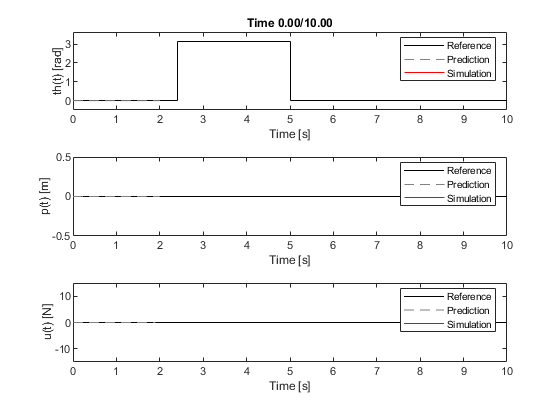

figure(1)
set(gcf,'Visible','on')

subplot(311)
stairs(t, x_ref(1,1:numel(t)), 'k-')
hold on
f_th_sol = plot(t(1:N+1), x_sol(1,:), '--', 'Color', 0.5*[1 1 1]);
f_th_sim = plot(t(1), x0(1), 'r');
hold off
f_title_time = title(sprintf('Time %4.2f/%4.2f', t(1), t(end)));
xlabel('Time [s]')
ylabel('th(t) [rad]')
legend('Reference', 'Prediction', 'Simulation')
ylim([-.5 pi+0.5])

subplot(312)
stairs(t, x_ref(3,1:numel(t)), 'k-')
hold on
f_p_sol = plot(t(1:N+1), x_sol(3,:), '--', 'Color', 0.5*[1 1 1]);
f_p_sim = plot(t(1), x0(3), 'r');
hold off
xlabel('Time [s]')
ylabel('p(t) [m]')
legend('Reference', 'Prediction', 'Simulation')
ylim([-0.5 0.5])

subplot(313)
stairs(t, u_ref(1,1:numel(t)), 'k-');
hold on
f_u_sol = stairs(t(1:N), u_sol, '--', 'Color', 0.5*[1 1 1]);
f_u_sim = stairs(t(1), 0, 'r');
hold off
xlabel('Time [s]')
ylabel('u(t) [N]')
legend('Reference', 'Prediction', 'Simulation')
ylim([umin umax])

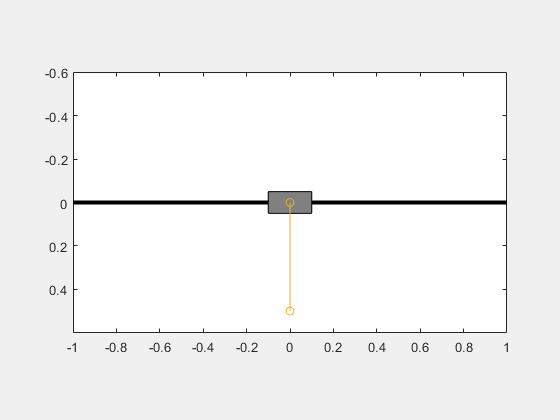


figure(2)
set(gcf,'Visible','on')
pole_length = l;
cart_vertices(:,1) = [-1; 1; 1; -1]*100e-3;
cart_vertices(:,2) = [-0.5; -0.5; 0.5; 0.5]*100e-3;
plot([-1 1], [0 0], 'k', 'LineWidth', 3)
hold on;
h_cart = fill(cart_vertices(:,1), cart_vertices(:,2), [.5 .5 .5]);
h_pole = plot([0, 0],[0,pole_length],'o-');                         % zaves
hold off;
axis equal;
axis([-1,1,-1.2*pole_length,1.2*pole_length]);
set(gca, 'YDir', 'reverse');

Run the simulation:

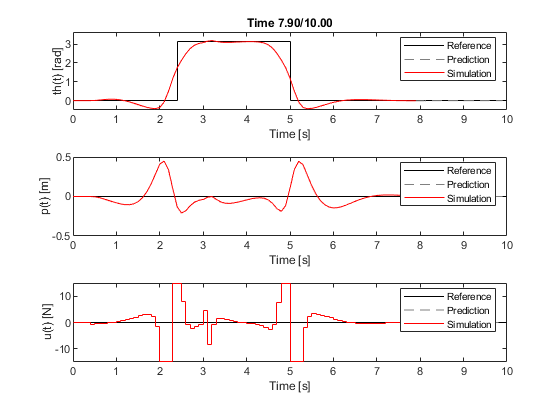

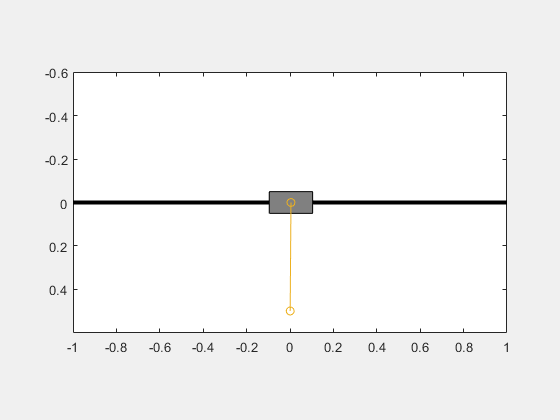

for i = 1:(numel(t)-1-N)
    % Shift the solution trajectories from the previous control period to obtain
    % the guess trajectories
    u_guess = [u_sol(:,2:end) u_sol(:,end)];
    x_guess = [x_sol(:,2:end) fs(x_sol(:,end), u_guess(:,end))];
    
    % Compute the sensitivities (matrices Ak, Bk, Ck, Dk, ...)
    [WN, JN, W, J, A, B, r, C, D, h, HN, hN] = computeSensitivities(x_guess, u_guess, x_ref(:, i:(i+N)), u_ref(:, i:(i+N-1)), Ws, WNs, Js, JNs, fs, As, Bs, hs, Cs, Ds, hNs, HNs);
    % Formulate the QP
    [Hbar, gbar, Abar, b0bar, Mbar, mbar] = LTV_MPC_to_QP(x(:,i), x_guess, WN, JN, W, J, A, B, r, C, D, h, HN, hN);
    % Solve the QP
    z_sol = quadprog(Hbar, gbar, Mbar, mbar, Abar, b0bar, [], [], [], optimoptions('quadprog', 'Display', 'off'));
    % Extract u_t from the output of the quadprog. The output contains
    % [dx_t; du_t; ...; dx_{t+N-1}; du_{t+N-2}; dx_{t+N}].
    
    z_sol_tmp = reshape(z_sol(1:end-n), n+m, N);
    
    dx_pred = [z_sol_tmp(1:n, :) z_sol(end-n+1:end)];
    du_pred = z_sol_tmp(n+1:n+m,:);
    
    % Current estimate of the optimal control and state trajectories
    x_sol = x_guess + dx_pred;
    u_sol = u_guess + du_pred;
    
    % The control input to be applied
    u(:,i) = u_sol(:,1);
    
    % Simulate a punch in the pole at time 3
    if(t(i) == 3)
        u(:,i) = u(:,i) + 30*rand()-15;
    end
    
    % You can even try to simulate some noise in the input signal
    %     u(:,i) = u(:,i) + randn;
    
    % Simulate the response of the system
    [~, x_new] =ode45(@(t, x_placeholder) f_c(x_placeholder, u(:,i)), [0 Ts], x(:,i));
    x(:,i+1) = x_new(end,:)';
    
    % Update the plots
    f_title_time.String = sprintf('Time %4.2f/%4.2f', t(i), t(end));
    
    f_th_sol.XData = t(i:(i+N));
    f_th_sol.YData = x_sol(1,:);
    f_th_sim.XData = t(1:i);
    f_th_sim.YData = x(1,1:i);
    
    f_p_sol.XData = t(i:(i+N));
    f_p_sol.YData = x_sol(3,:);
    f_p_sim.XData = t(1:i);
    f_p_sim.YData = x(3,1:i);
    
    f_u_sol.XData = t(i:(i+N-1));
    f_u_sol.YData = u_sol;
    f_u_sim.XData = t(1:i);
    f_u_sim.YData = u(1:i);
    
    h_cart.Vertices(:,1) = cart_vertices(:,1) + x(3,i);
    pole_pos = [x(3,i) + pole_length*sin(x(1,i)), pole_length*cos(x(1,i))];
    h_pole.XData = [x(3,i); pole_pos(1)];
    h_pole.YData = [0; pole_pos(2)];
    
    drawnow
    end